# Descarga batería

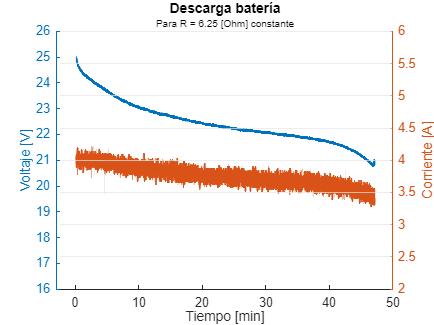

data = readmatrix("Muestras_arduino.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
time_1      = time_1/(1000*60);
volt_1      = data(:, 2);
ampere_1    = data(:, 3);

clf %% clean figure

figure(1)
hold on 
yyaxis left
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 1.5)
ylim([16 26]);
ylabel("Voltaje [V]");

yyaxis right

plot(time_1,ampere_1,'LineStyle', '-', 'LineWidth', 1.5)
ylim([2 6]);
ylabel("Corriente [A]");

% This effectively brings the "Left" side to the top layer
xlabel("Tiempo [min]");
xlim([-3 50])
title("Descarga batería");
subtitle("Para R = 6.25 [Ohm] constante",'FontSize',8);

grid off; % Turn off the default "left-aligned" grid

% Get the tick positions of the right axis
ticks = get(gca, 'YTick');

% Draw horizontal lines at every tick mark
% 'HandleVisibility','off' ensures these don't show up in a legend
yline(ticks, 'Color', [0.9 0.9 0.9], 'LineWidth', 0.5, 'HandleVisibility', 'off');

hold off


% exportgraphics(gcf,"Figuras/inrush_switch.png");

# Av dsg

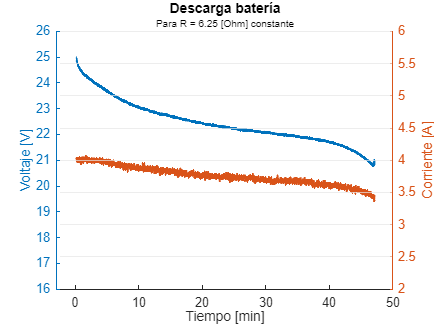

data = readmatrix("Muestras_arduino.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
time_1      = time_1/(1000*60);
volt_1      = data(:, 2);
ampere_1    = data(:, 3);
ampere_1    = movmean(ampere_1,8);

clf %% clean figure

figure(2)
hold on 
yyaxis left
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 1.5)
ylim([16 26]);
ylabel("Voltaje [V]");

yyaxis right

plot(time_1,ampere_1,'LineStyle', '-', 'LineWidth', 1.5)
ylim([2 6]);
ylabel("Corriente [A]");

% This effectively brings the "Left" side to the top layer
xlabel("Tiempo [min]");
xlim([-3 50])
title("Descarga batería");
subtitle("Para R = 6.25 [Ohm] constante",'FontSize',8);

grid off; % Turn off the default "left-aligned" grid

% Get the tick positions of the right axis
ticks = get(gca, 'YTick');

% Draw horizontal lines at every tick mark
% 'HandleVisibility','off' ensures these don't show up in a legend
yline(ticks, 'Color', [0.9 0.9 0.9], 'LineWidth', 0.5, 'HandleVisibility', 'off');

hold off

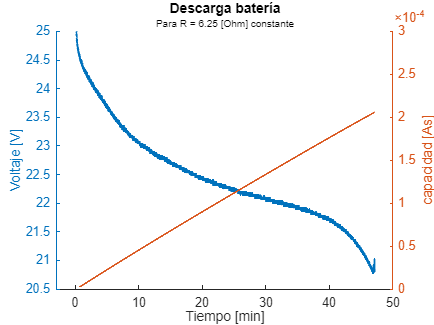

clear pwr_1 chg_1 chg_2

for i = 1:11065
    pwr_1(i) = mean([ampere_1(i+1) ampere_1(i)]) *mean([volt_1(i+1) volt_1(i)]);
    if i == 1
        chg_2(i) = 0;
        chg_1(i) = 0;
        continue
    end
    chg_1(i) = chg_1(i-1) + pwr_1(i) * (time_1(i+1) - time_1(i));
    chg_2(i) = chg_2(i-1) + (mean([ampere_1(i+1) ampere_1(i)]) * (time_1(i+1) - time_1(i))) * (1/3600) * (0.0042)  ;
end
chg_1 = [chg_1 chg_1(end)]; %Ah
chg_2 = [chg_2 chg_2(end)]; %Wh
pwr_1 = [pwr_1 pwr_1(end)];

clf

figure(3)
hold on 
yyaxis left
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 1.5)
% ylim([16 26]);
ylabel("Voltaje [V]");

yyaxis right

plot(time_1,chg_2,'LineStyle', '-', 'LineWidth', 1.5)
% ylim([2 6]);
% ylabel("powa [W]");
% ylabel("capacidad [wh]");
ylabel("capacidad [As]");

% This effectively brings the "Left" side to the top layer
xlabel("Tiempo [min]");
xlim([-3 50])
title("Descarga batería");
subtitle("Para R = 6.25 [Ohm] constante",'FontSize',8);

hold off